# A. Double side-band – suppressed carrier modulation :

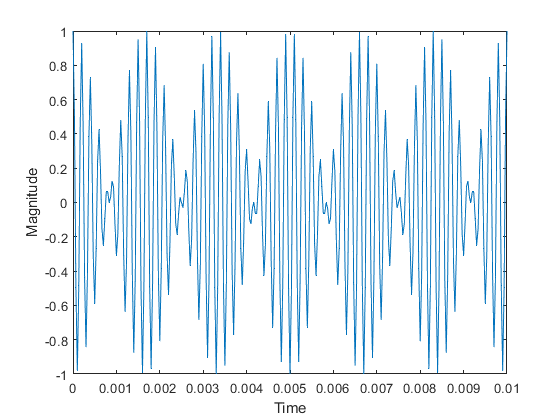


Fs = 30000;
dt = 1/Fs;
StopTime = 0.5;
t = (0:dt:StopTime-dt)';
N = size(t,1);
Fc1 = 300;
x1 = cos(2*pi*Fc1*t);
Fc2 = 5000;
x2 = cos(2*pi*Fc2*t);
x=x1.*x2;
% subplot(2,1,1);
plot(t,x);
axis([0 1/100 -1 1]);
xlabel('Time');
ylabel('Magnitude');

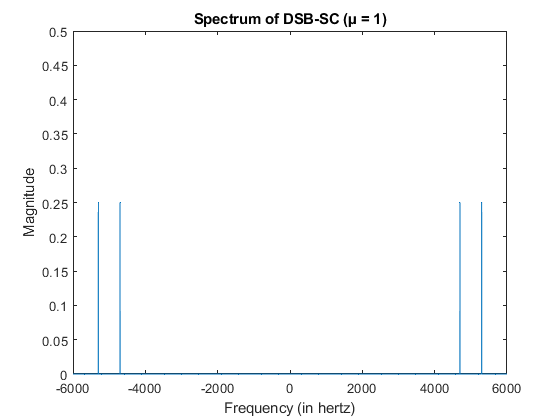


X = fftshift(fft(x));
dF = Fs/N;
f = -Fs/2:dF:Fs/2-dF;
% subplot(2,1,2);
plot(f,abs(X)/N);
title("Spectrum of DSB-SC (µ = 1)");
axis([-6000 6000 0 0.5]);
xlabel('Frequency (in hertz)');
ylabel('Magnitude');

## B. Double side-band – with carrier modulation :

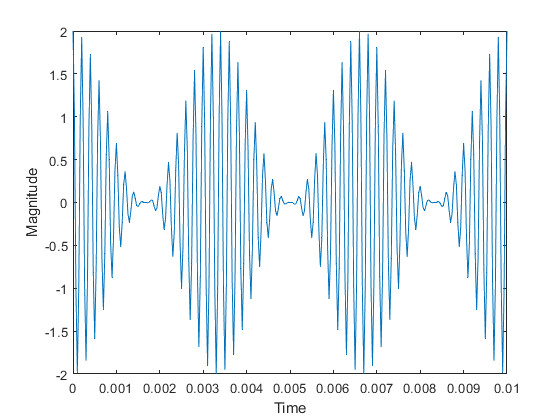

Fs = 30000;
dt = 1/Fs;
StopTime = 0.5;
t = (0:dt:StopTime-dt)';
N = size(t,1);
Fc1 = 300;
x1 = cos(2*pi*Fc1*t);
Fc2 = 5000;
x2 = cos(2*pi*Fc2*t);
x=(1+x1).*x2;
% subplot(2,1,1);
plot(t,x);
axis([0 1/100 -2 2]);
xlabel('Time');
ylabel('Magnitude')

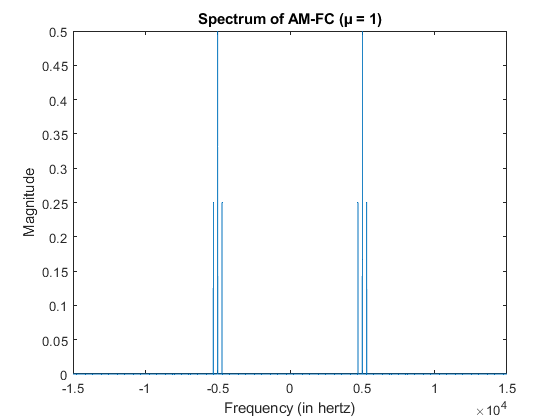

X = fftshift(fft(x));
dF = Fs/N;
f = -Fs/2:dF:Fs/2-dF;
%% Plot the spectrum:
% subplot(2,1,2);
plot(f,abs(X)/N);
title("Spectrum of AM-FC (µ = 1)");
xlabel('Frequency (in hertz)');
ylabel('Magnitude');

## C. 50% AM modulation (modulation index = 0.5) :

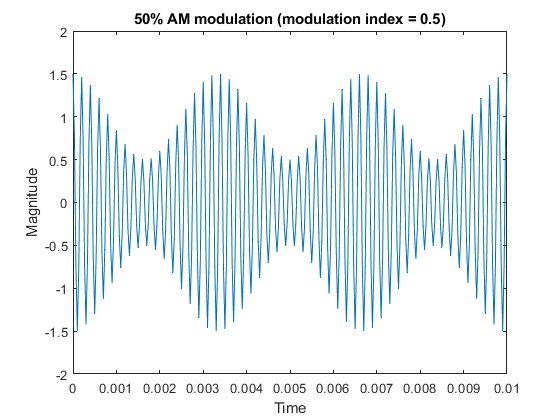

Fs = 30000;
dt = 1/Fs;
StopTime = 0.5;
t = (0:dt:StopTime-dt)';
N = size(t,1);
Fc1 = 300;
x1 = cos(2*pi*Fc1*t);
Fc2 = 5000;
x2 = cos(2*pi*Fc2*t);
x=(1+0.5*x1).*x2;
% subplot(2,1,1);
plot(t,x);
axis([0 1/100 -2 2]);
xlabel('Time');
ylabel('Magnitude');
title("50% AM modulation (modulation index = 0.5)")

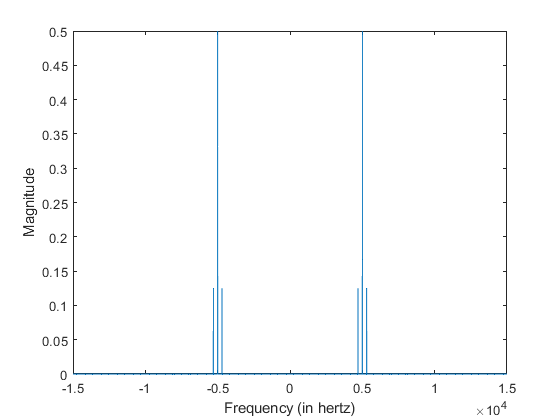


X = fftshift(fft(x));
dF = Fs/N;
f = -Fs/2:dF:Fs/2-dF;
% subplot(2,1,2);
plot(f,abs(X)/N);
zoom on
xlabel('Frequency (in hertz)');
ylabel('Magnitude');

## D. Two tone DSB_SC (M.I=1) :

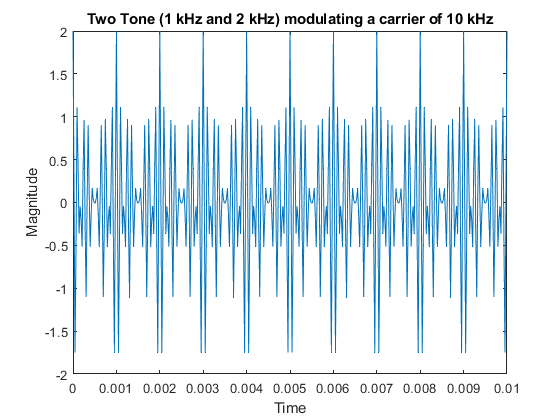

Fs = 43000;
dt = 1/Fs;
StopTime = 0.5;
t = (0:dt:StopTime-dt)';
N = size(t,1);
Fc1 = 1000;
x1 = cos(2*pi*Fc1*t);
Fc2 = 2000;
x2 = cos(2*pi*Fc2*t);
Fc3 = 10000;
x3 = cos(2*pi*Fc3*t);
x=(x1+x2).*x3;
% subplot(2,1,1);
plot(t,x);
title("Two Tone (1 kHz and 2 kHz) modulating a carrier of 10 kHz");
xlabel('Time');
ylabel('Magnitude');
axis([0 1/100 -2 2]);

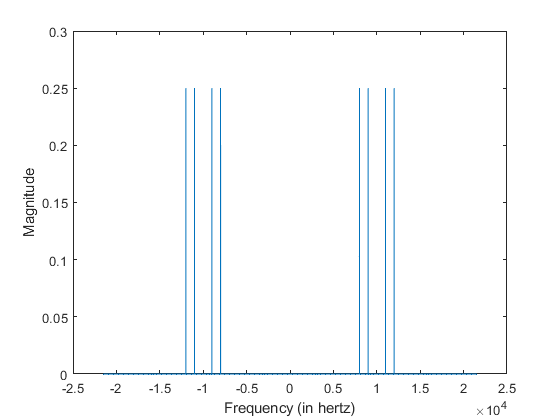

X = fftshift(fft(x));
dF = Fs/N;
f = -Fs/2:dF:Fs/2-dF;
% subplot(2,1,2);
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
ylabel('Magnitude');

## E. Two-tone DSB with carrier - 100% AM modulation (modulation index = 1) :

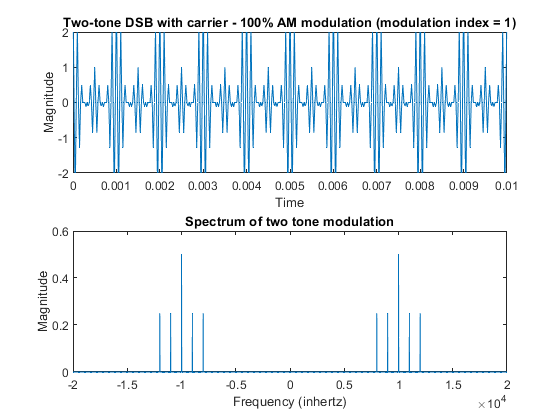

Fs = 40000;
dt = 1/Fs;
StopTime = 1;
t = (0:dt:StopTime-dt)';
N = size(t,1);
Fc1 = 1000;
x1 = cos(2*pi*Fc1*t);
Fc2 = 2000;
x2 = cos(2*pi*Fc2*t);
Fc3 = 10000;
x3 = cos(2*pi*Fc3*t);
x=(1+(x1+x2)).*x3;
% subplot(2,1,1);
plot(t,x);
title("Two-tone DSB with carrier - 100% AM modulation (modulation index = 1)")
xlabel('Time');
ylabel('Magnitude');
axis([0 1/100 -2 2]);
X = fftshift(fft(x));
dF = Fs/N;
f = -Fs/2:dF:Fs/2-dF;
% subplot(2,1,2);
plot(f,abs(X)/N);
title("Spectrum of two tone modulation");
xlabel('Frequency (inhertz)');
ylabel('Magnitude');